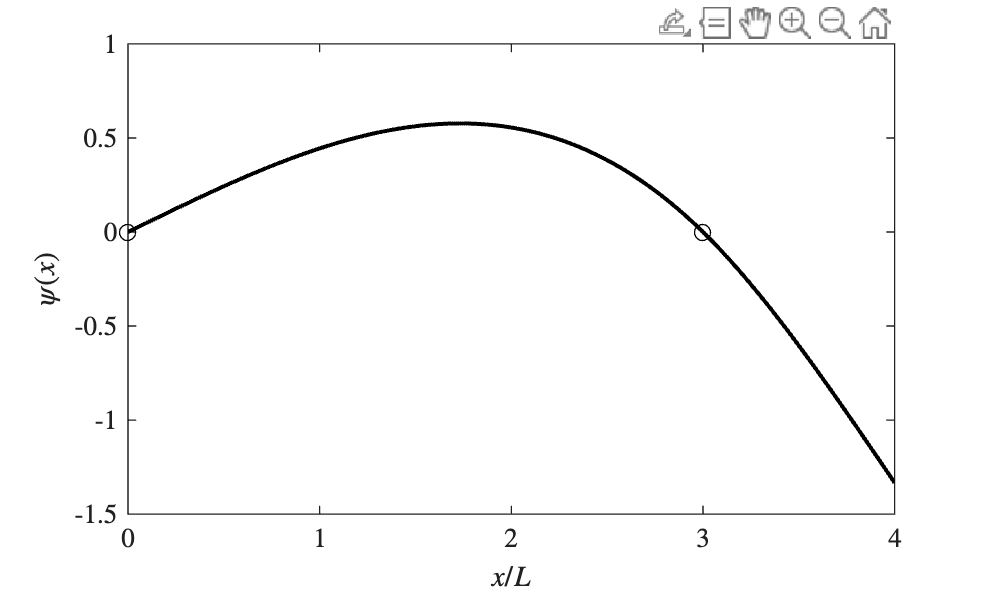

close all
% Set default interpreter to Latex
set(groot, 'defaultTextInterpreter', 'latex');

% Space discretization

x = 0:0.01:4;

psi_left = -1/18*x.^3 + 1/2*x;
psi_right = -2*x.^2 + 1/6*x.^3 + 13/2*x - 6;

psi = (x<3).*psi_left + (x>3).*psi_right;

supports_x = [0, 3];
supports_y = [0, 0];

figure()
plot(x, psi, 'k-', LineWidth=1.5)
hold on
plot(supports_x, supports_y, 'ko')
% Set default tick intepreter to latex
set(gca, 'TickLabelInterpreter', 'latex');
xlabel('$x/L$')
ylabel('$\psi(x)$')